clc; % clear command window
clearvars; % clear variables from memory
close all; % close all figures

% Total time
t = 0:0.01:3;

Mass - Spring - Damper System

mass  = 1 kg

damping coefficient = 10 Ns/m

spring constant = 20 N/m

Force = 1 N

% PROBLEM 1 - OPEN LOOP (NO FEEDBACK) 
num = [0 0 1];
den = [1 10 20];
sys = tf(num, den);
sys

sys =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.



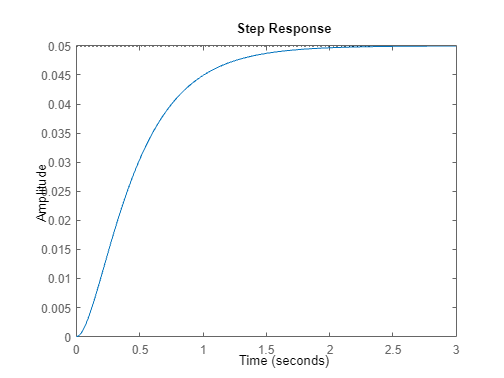

% Open-Loop step response
step(sys)

% PROBLEM 2 - CLOSED LOOP (UNITY FEEDBACK)
P2 = feedback(sys, 1);
P2

P2 =
 
         1
  ---------------
  s^2 + 10 s + 21
 
Continuous-time transfer function.



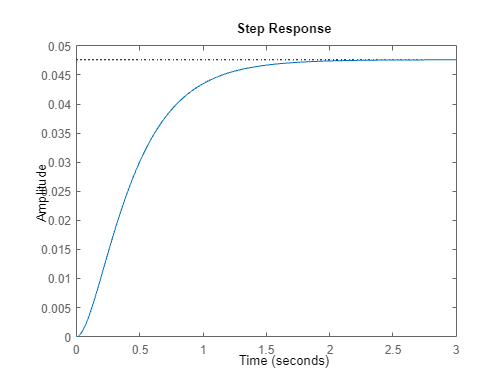

% Closed-Loop step response
step(P2,t)

% PROBLEM 3 - CLOSED LOOP WITH UNITY FEEDBACK AND PROPORTIONAL CONTROL
Kp = 300;
C = pid(Kp)

C =
 
  Kp = 300
 
P-only controller.



P3 = feedback(C*sys, 1);

P3 =
 
        300
  ----------------
  s^2 + 10 s + 320
 
Continuous-time transfer function.



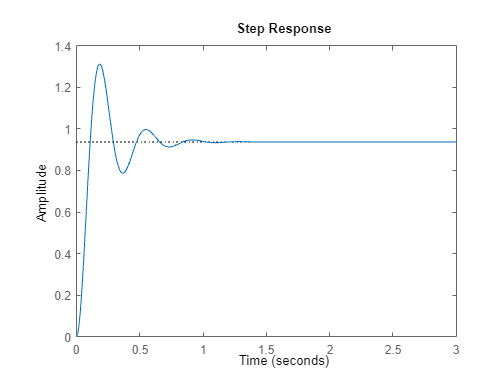

step(P3,t)

% PROBLEM 4 - CLOSED LOOP WITH UNITY FEEDBACK AND PROPORTIONAL-DERIVATIVE CONTROL
Kp = 300;
Kd = 10;
C = pid(Kp,0,Kd);
P4 = feedback(C*sys, 1);
P4

P4 =
 
     10 s + 300
  ----------------
  s^2 + 20 s + 320
 
Continuous-time transfer function.



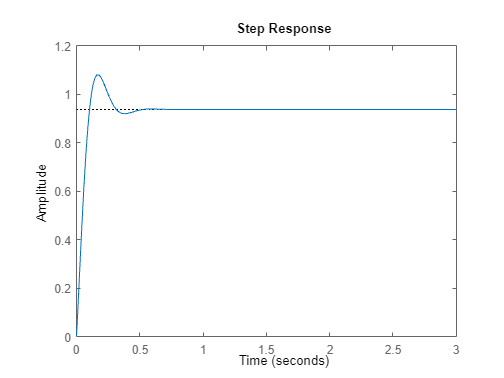

% Closed-Loop step response
step(P4,t)

% P5: PROPORTIONAL-INTEGRAL CONTROL
Kp = 300;
Ki = 70;
C = pid(Kp,Ki,0);
P5 = feedback(C*sys, 1);
P5

P5 =
 
         300 s + 70
  -------------------------
  s^3 + 10 s^2 + 320 s + 70
 
Continuous-time transfer function.



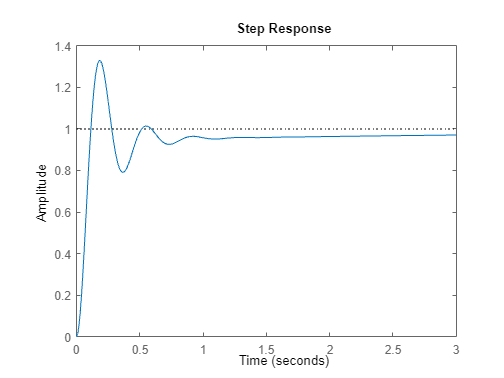

% Closed-Loop step response
step(P5,t)

% P6: PROPORTIONAL-INTEGRAL-DERIVATIVE CONTROL
Kp = 350;
Ki = 300;
Kd = 50;
C = pid(Kp,Ki,Kd);
P6 = feedback(C*sys, 1);
P6

P6 =
 
     50 s^2 + 350 s + 300
  --------------------------
  s^3 + 60 s^2 + 370 s + 300
 
Continuous-time transfer function.



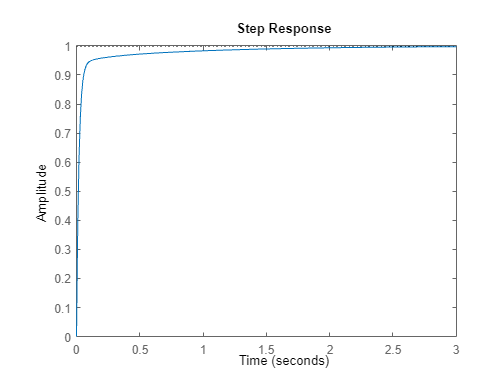

% Closed-Loop step response
step(P6,t)